# **The Fabry-Perot Interferometer**

Ian Cooper

School of Physics, University of Sydney

DOING PHYSICS WITH MATLAB: www.physics.usyd.edu.au/teach_res/mp/mphome.htm

Documentation: www.physics.usyd.edu.au/teach_res/mp/doc/op1010A.htm

Mscripts: www.physics.usyd.edu.au/teach_res/mp/mscripts

Matlab 2018b  181212     op_LE_010.mlx

The Fabry-Perot interferometer is instrument used in precision wavelength measurements and has extremely high resolution. The simulation allows one to investigate the general features of the interferometer. The instrument is very sensitive, so you need to be careful in changing the input parameters. You may need to adjust the limits for the slider controls.

## Explorations

- Check the simulation calculations manually.

- Check the dependence on the angular location of peaks with the order number m.

- Check the dependence of the sharpness of the peaks with reflectance R.

- Investigate how the irradiance pattern changes with variations in the input parameters.

-     How does the position of the peaks change as you change the wavelength?

-     How does the position of the peaks change as you change distance between the plates d?

-     Change the values of wavelength and separation distance but keep the ratio constant. How does the interference pattern change?

-    Under what conditions is the irradiance a maximum or a minimum at the centre of the circluar fringe pattern.

- **Resolving Power**: Investigate the resolving power of the interferometer. You can conclude unambiguously two wavelengths are present when the dip in between two peaks is about 81% of the maximum peak values. You will need to use the zoom feature in the irradiance plot.

- **Free spectral range**: Investigate the free spectral range of the instrument. The free spectral range is the smallest wavelength difference for which different orders start to overlap. 

- Investiagte the **D spectral line of sodium**. This line is a doublet of two distinct spectral lines of wavelengths 589.0 nm and 589.6 nm.

- What is the significance of the finesse of the interferometer?

## **INPUTS**

It is is often easier to enter values in the input boxes rather than use the slider controls 

clear
close all
clc

% Wavelength [nm]
  lambda = 656.281;  
% Wavelength increment [nm]
  dlambda = 0.136;   
% Reflectance (intensity)
  R = 0.96;  
% Distance between plates (separation distance) [m] 
  d = 0.0000206728515;   
% Max viewing angle [deg]
 thetaMax =15;  
% Min viewing angle  [deg]
  thetaMin = 0;                           
% number of angle increments
  num = 2500;                        

## **CALCULATIONS**

 % Wavelength 1  [m]       
   lambda1 = lambda*1e-9; 
 % Wavelength 2  [m] 
   lambda2 = (lambda + dlambda)*1e-9;        
 % Viewing angle  [deg]    
   theta = linspace(thetaMin,thetaMax, num); 


% Irradiance S as a function of angle theta
   [S1] = FabryPerot(theta,lambda1,R,d);
   [S2] = FabryPerot(theta,lambda2,R,d);

% Normalized irradiances and total irradiance S
   S1 = S1./max(S1);
   S2 = S2./max(S2);
   S = S1 + S2;
   S = S./max(S);

% Findpeaks in irradiance patterns   
 [A1, B1] = findpeaks(S1);
 m1 = (2*d) .* cosd(theta(B1)) ./ lambda1;

  [A2, B2] = findpeaks(S2);
  m2 = (2*d) .* cosd(theta(B2)) ./ lambda2;
  cN = min([length(B1);length(B2)]);
  cN1 = cN;
  if cN > 4
      cN1 = 4;
  end
   
% Interferometer parameters
%    coefficient of finesse  
       F = 4*R/(1-R)^2;
%    Resolving power  (first peak only)
       R_P =  m1(1)*pi*sqrt(F)/2;
%    Resolving power: min wavelength difference
      lambda_min = 2*lambda1/(m1(1)*pi*sqrt(F));
%    Free spectral range
      FSR = lambda1^2/(2*d);
%   Finesse
     F_FP = pi*sqrt(F)/2;     

## **INTERFEROMETER SETUP**

The interferometer is an extremely sensitive instrument. Slight variations in the input parameters can dramatically change the irradiance distribution. Rather than use a trial and error approach to altering the variables, we can estimate a possible range for the separation distance between the interferometer plates from the inputs of reflectance, wavelength and wavelength increment. The minimum distance between the plates is estimated from the resolving power and the maximum separation distance of the plates is estimated from the free spectral range. A summary in the Output Window for possible values of the plate separation distance and maximum viewing angle for the irradiance distribution are displayed.  These values then can be entered into the controls (inputs) for the plate separation distance and max angle for viewing the irradiance distribution.

     
% Interferometer Setup: estimate for range of plate separation
  R_Pmin = lambda/dlambda;
  m_min = round(2*R_Pmin / (pi*sqrt(F)));
  d_min = m_min * lambda1 /2;
  d_max = lambda1^2 / (2*dlambda*1e-9);
  m_max = round(2*d_max/lambda1);
  theta_max_min = acosd((m_min-1) * lambda1 / (2*d_min));
  theta_max_max = acosd((m_max-1) * lambda1 / (2*d_max));


  fprintf('m_min = %2.2f  m \n',m_min)

m_min = 63.00  m 


  fprintf('d_min = %2.8e  m \n',d_min)

d_min = 2.06728515e-05  m 


  fprintf('d_max = %2.8e  m \n',d_max)

d_max = 1.58347335e-03  m 


  fprintf('theta_max_min = %2.2f  m \n',theta_max_min)

theta_max_min = 10.22  m 


  fprintf('theta_max_max = %2.2f  m \n',theta_max_max)

theta_max_max = 0.90  m 


## **GRAPHICS**

Plots for irradiances S1 and S2 are color coded to their wavelength by calling the function **colorCode.m**. 

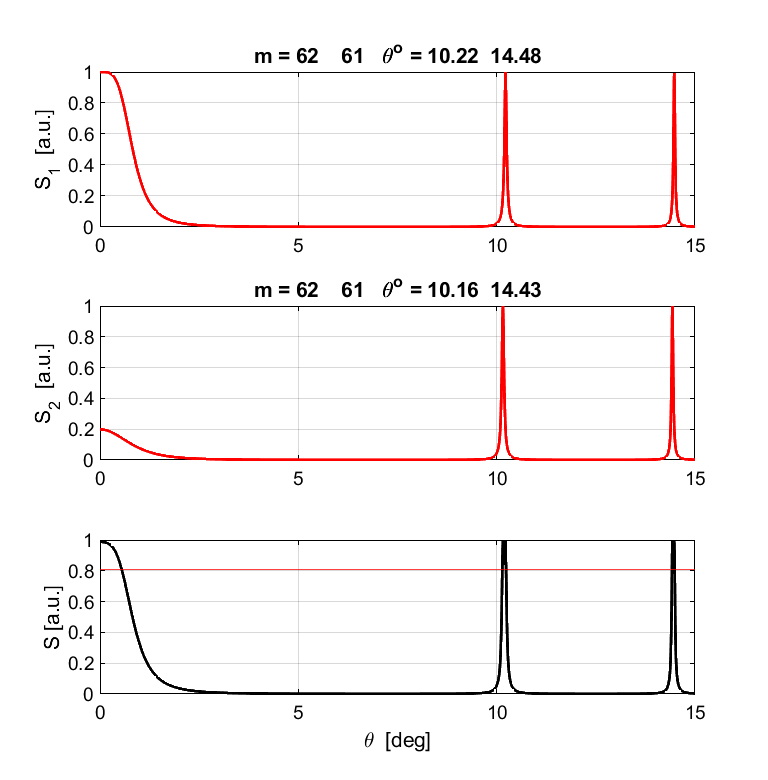

 figure(1);
  pos = [0.30 0.05 0.4 0.65];
  set(gcf,'Units','normalized');
  set(gcf,'Position',pos);
  
  xP = theta;
  subplot(3,1,1)
    yP = S1;
    col = ColorCode(lambda1);
    plot(xP,yP,'linewidth',2,'color',col)
    ylabel('S_1  [a.u.]')
    tm1 = 'm = ';
    tm2 = num2str(m1(1:cN1),'%4.0f  ');
    tm3 = '   \theta^o = ';
    tm4 = num2str(theta(B1(1:cN1)),'%1.2f  ');
    tm = [tm1 tm2 tm3 tm4];
    title(tm);
    grid on
    set(gca,'fontsize',14)
    set(gca,'ytick',0:0.2:1)
  
  subplot(3,1,2)
    yP = S2;
    col = ColorCode(lambda2);
    plot(xP,yP,'linewidth',2,'color',col)
    set(gca,'fontsize',14)
    ylabel('S_2  [a.u.]')
    set(gca,'ytick',0:0.2:1)
    grid on
    
    
    
    tm1 = 'm = ';
    tm2 = num2str(m2(1:cN1),'%4.0f  ');
    tm3 = '   \theta^o = ';
    tm4 = num2str(theta(B2(1:cN1)),'%1.2f  ');
    tm = [tm1 tm2 tm3 tm4];
    title(tm);
    
  subplot(3,1,3)
    yP = S;
    plot(xP,yP,'k','linewidth',2)
    ylabel('S [a.u.]')
    set(gca,'ytick',0:0.2:1)
    set(gca,'fontsize',14)
    hold on
    plot([thetaMin thetaMax],[0.81 0.81],'r')

    xlabel('\theta  [deg]')
  
    whitebg([1 1 1])
    box on
    grid on
    set(gca,'fontsize',14)

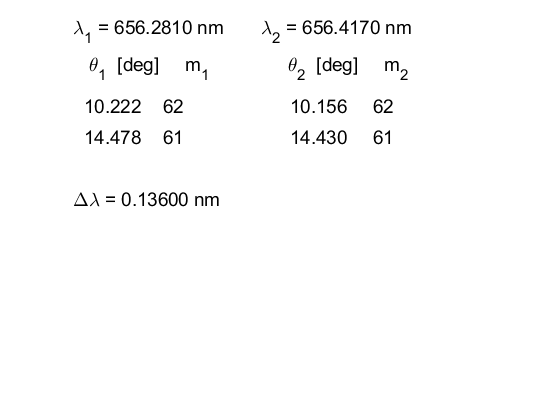

    
   figure(2)
%   pos = [0 0 0.40 0.75];
%   set(gcf,'Units','normalized');
%   set(gcf,'Position',pos);
    set(gcf,'color','w');
  
   xlim([0 120])
   ylim([0 220])
   h = 220; dh = -24;
  
   tm1 = '\lambda_1 = ';
   tm2 = num2str(lambda1*1e9,'%2.4f nm  \n');
   tm = [tm1 tm2];
   text(0,h,tm,'fontsize',14)
 
   tm1 = '\lambda_2 = ';
   tm2 = num2str(lambda2*1e9,'%2.4f nm  \n');
   tm = [tm1 tm2];
   text(52,h,tm,'fontsize',14)
   h = h+dh;   
   text(0,h,'   \theta_1  [deg]     m_1               \theta_2  [deg]     m_2','fontsize',14)
   h = h+dh;
  
  dh = -20;
  
  
  for c1 = 1: cN
      tm1 = num2str(theta(B1(c1)),'%2.3f  \n'); 
      text(3,h,tm1,'fontsize',14)
      tm1 = num2str(m1(c1),'%2.0f  \n'); 
      text(25,h,tm1,'fontsize',14)
      
      tm1 = num2str(theta(B2(c1)),'%2.3f  \n'); 
      text(60,h,tm1,'fontsize',14)
      tm1 = num2str(m2(c1),'%2.0f  \n'); 
      text(83,h,tm1,'fontsize',14)
      h = h+dh;
  end
     h = h+dh;
     tm1 = '\Delta\lambda = ';
     tm2 = num2str(dlambda,'%1.5f nm  \n');
     tm = [tm1 tm2];
     text(0,h,tm,'fontsize',14)
   
     axis off      

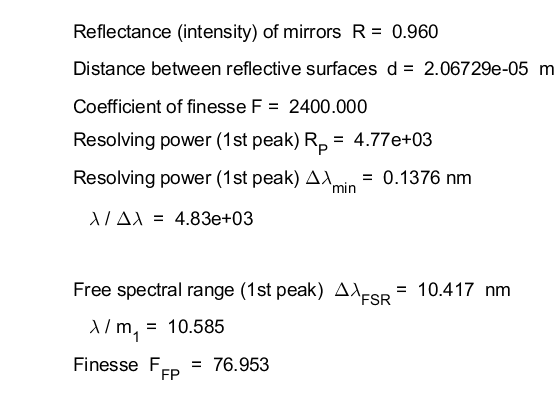

   
     
figure(3)
 % pos = [0 0 0.25 0.30];
 % set(gcf,'Units','normalized');
 % set(gcf,'Position',pos);
  set(gcf,'color','w');

  xlim([0 120])
  ylim([0 220])
  h = 220; dh = -24;
  
  tm1 = 'Reflectance (intensity) of mirrors  R =  ';
  tm2 = num2str(R,'%2.3f   \n');
  tm = [tm1 tm2];
  text(0,h,tm,'fontsize',14)
  h = h+dh;
  
  tm1 = 'Distance between reflective surfaces  d =  ';
  tm2 = num2str(d,'%2.5e  m  \n');
  tm = [tm1 tm2];
  text(0,h,tm,'fontsize',14)
  h = h+dh;
  
  tm1 = 'Coefficient of finesse F =  ';
  tm2 = num2str(F,'%2.3f  \n');
  tm = [tm1 tm2];
  text(0,h,tm,'fontsize',14)
  h = h+dh;
   
  tm1 = 'Resolving power (1st peak) R_P =  ';
  tm2 = num2str(R_P,'%2.2e  \n');
  tm = [tm1 tm2];
  text(0,h,tm,'fontsize',14)
  h = h+dh;
  
  tm1 = 'Resolving power (1st peak) \Delta\lambda_{min} =  ';
  tm2 = num2str(lambda_min*1e9,'%2.4f nm  \n');
  tm = [tm1 tm2];
  text(0,h,tm,'fontsize',14)
  h = h+dh;
  
  tm1 = '   \lambda / \Delta\lambda  =  ';
  tm2 = num2str(lambda/dlambda,'%2.2e  \n');
  tm = [tm1 tm2];
  text(0,h,tm,'fontsize',14)
  h = h+2*dh;
  
  tm1 = 'Free spectral range (1st peak)  \Delta\lambda_{FSR} =  ';
  tm2 = num2str(FSR*1e9,'%2.3f  nm\n');
  tm = [tm1 tm2];
  text(0,h,tm,'fontsize',14)
  h = h+dh; 
  
  tm1 = '   \lambda / m_1 =  ';
  tm2 = num2str(lambda/m1(1),'%2.3f  \n');
  tm = [tm1 tm2];
  text(0,h,tm,'fontsize',14)
  h = h+dh;
  
  tm1 = 'Finesse  F_{FP}  =  ';
  tm2 = num2str(F_FP,'%2.3f \n');
  tm = [tm1 tm2];
  text(0,h,tm,'fontsize',14)
  h = h+dh; 
  
  axis off

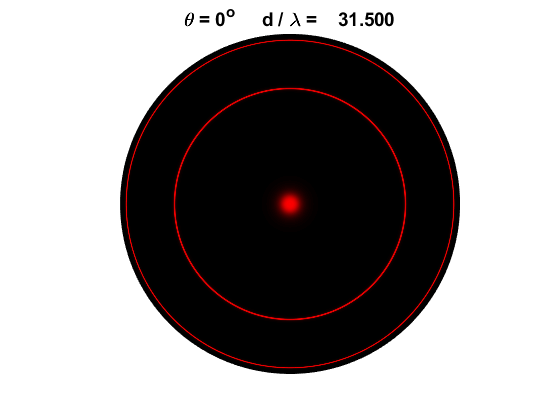

  
  
 figure(4)
     nT = 720;
     xx = zeros(num,nT); yy = zeros(num,nT); Sxy = zeros(num,nT);
     r = 1: num; A = linspace(0,2*pi,nT);
     for c1 = 1 : num
       for c2 = 1 : nT
         xx(c1,c2) = r(c1) * cos(A(c2));
         yy(c1,c2) = r(c1) * sin(A(c2));
       end
     end

     for c1 = 1 : nT
     Sxy(:,c1) = S;
     end
     
     myMap = zeros(64,3);
     for c1 = 1:64
     myMap(c1,:) = col;
     end
     pcolor(xx,yy,Sxy)
     shading interp
     axis equal
       shadingMap = gray(64);
       colormap(shadingMap(:,1)*col);
  %   colormap(copper)
     axis off
     whitebg([1 1 1])
     box off
     
     tm1 = '\theta = 0^o     d / \lambda =    ';
     tm2 = num2str(d/lambda1,'%4.3f \n');
     tm = [tm1 tm2];
     title(tm,'fontsize',14)

## **FUNCTIONS**

function [S] = FabryPerot(theta,lambda,R,d)

 F = 4*R / (1 - R)^2;
 
 delta = (2*pi) .* (2*d*cosd(theta) ./ lambda);
 
 S = 1 ./ (1 + F .* sin(delta/2).^2);

end
